Fundamentos de control                                                                                                                                                                                                       

# Descripción externa e interna

### Descripción interna de sistemas

La **teoría de control clásica** trabaja con sistemas SISO y LTI, emplea métodos de respuesta en frecuencia y el lugar de las raíces, y conduce a sistemas estables que satisfacen un conjunto de requisitos pero que no son óptimos desde ningún punto de vista.

No obstante, las plantas modernas presentan cada vez una mayor complejidad, debido a que realizan cada vez tareas más complejas y de mayor precisión. La necesidad de controlar este tipo de plantas, que típicamente presentan multiples entradas y salidas (MIMO), y pueden ser no lineales y variantes en el tiempo, junto con la diponibilidad de computadoras digitales, impulsó allá por 1960 el desarrollo de la **teoría de control moderna**. Esta teoría considera la **descricpción interna** de los sistemas a controlar en lugar de la descripción externa empleada por la teoría clásica. Veamos en qué consiste. 

## `1. Modelado en el Espacio de Estados`

La descripción interna de sistemas se basa en el concepto de **estado**: conjunto más pequeño de **variables** (llamadas **de estado**) de forma que si se conoce su valor en $t=t_0$ y la(s) entrada(s) al sistema para $t\ge t_0$, estos determinan completamente la evolución de dichas variables de estasdo y la(s) funcione(s) de salida mediante las ecuaciones:

- Ecuación de estado: $x^{\prime } \left(t\right)=f\left(x\left(t\right),u\left(t\right)\right)$

- Ecuación de salida:  $y\left(t\right)=g\left(x\left(t\right),u\left(t\right)\right)$

donde:

- $x$ es **vector de estado**, el cual contiene las recién presentadas variables de estado, y refleja el estado del sitema en un instante de tiempo,

- $f\left(\cdot \right)$ es la **función de transición**, la cuál permite conocer la evolución en función del estado actual y la entrada, y

- $g\left(\cdot \right)$ es la** función de salida**, que permite conocer la salida del sistema en función del estado y de su entrada.

Aunque se puede definir un espacio de estados que no tenga una relación evidente con el funcionamiento del sistema, es conveniente que las variables de estado tengan un significado físico. **¡OJO!** Una de las principales virtudes de la descripción interna es realmente esta. Al trabajar con la función de transferencia, la descripción externa "sólo" aporta informacón sobre la relación entre la transformadas de Laplace de la salida y de la entrada del sistema. Por contra, la descripción interna nos permite trabajar con otras variables de interés. Ya veremos ejemplos de esto.

Si un sistema es lineal, las ecuaciones de estado pueden expresarse de la siguiente forma:

- Ecuación de estado: $x^{\prime } \left(t\right)=\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right)$

- Ecuación de salida:  $y\left(t\right)=\textrm{Cx}\left(t\right)+\textrm{Du}\left(t\right)$

Además, si el sistema tiene `n `variables de estado, `p` entradas y `m` salidas, entonces:

- $A$, también llamada **matriz dinámica **(o de **estado**), es de dimensión $n\;x\;n$.

- $B$, también llamada **matriz de control **(o de **entrada**), es de dimensión $n\;x\;p$.

- $C$, también llamada **matriz de salida**, es de dimensión $m\;x\;n$.

- $D$, también llamada **matriz de influencia directa**, es de dimensión $m\;x\;p$.

Cabe destacar que cualquier estado puede representarse mediante un punto en el **espacio de estados**: espacio $n$-dimensional donde cada una de las $n$variables de estados se correspondonde con un eje de coordenadas. 

### `1.1 El comando ss`

MATLAB nos facilita el trabajo con la representación interna de sistemas con el comando `ss`. Su sintaxis es:

- `sys = ss(A,B,C,D):` Crea un modelo de espacio de estado representando el modelo continuo visto anteriormente, esto es, mediante las matrices `A`, `B`, `C`, y `D`*,* que definen las ecuaciones de estado y de salida. Ejemplo:

A = [0 1;-5 -2]; % Matriz dinámica o de estado 
B = [0;3];       % Matriz de control o de entrada
C = [0 1];       % Matriz de salida
D = 0;           % Matriz de influencia directa
sys_ss = ss(A,B,C,D)

sys_ss =
 
  A = 
       x1  x2
   x1   0   1
   x2  -5  -2
 
  B = 
       u1
   x1   0
   x2   3
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


### `1.2 Ejemplo descripción interna: Circuito LRC serie`

El siguiente esquema muestra un circuito LRC típico compuesto por una bobina, una resistencia y un condensador. En este circuito, la entrada al sistema es la tensión de entrada $V_e$, y la de salida es la caída de tensión en el condensador, $V_s$. Es decir, nuestro circuito cuenta con una tensión de entrada variable, y estamos interesados en controlar la caída de tensión en el condensador.

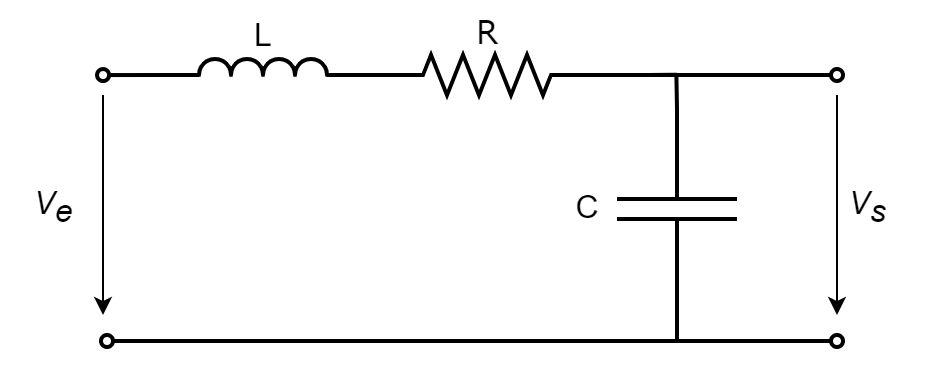

Como ingenieros de control, el primer paso para conseguirlo es modelar matemáticamente el comportamiento dinámico del sistema. Para ello se van a obtener sus ecuaciones diferenciales a partir de las leyes físicas que gobiernan el sistema. En este caso, aplicando la ley de tensiones de Kirchhoff obtenemos:


$$\begin{array}{l}
{\left(1\right)\;V}_e \left(t\right)=L\cdot \frac{\partial i}{\partial \;t}+R\cdot i\left(t\right)+\frac{1}{C}\int i\;\textrm{dt}\\
{\left(2\right)\;V}_s \left(t\right)=\frac{1}{C}\cdot \int i\;\textrm{dt}
\end{array}$$


Donde (1) expresa que la fuente de tensión del sistema $V_e \left(t\right)$ tiene que ser igual a la caída de tensión sufrida en cada uno de los componentes del mismo, y (2) expresa el valor de la caída de tensión en el condensador $V_s \left(t\right)$.

En este punto hay varias maneras de proceder en función de las variables de estado elegidas, pero en este caso perseguimos una ecuación diferencial expresada en función de la entrada y salida del sistema, por lo cual hay que buscar reemplazar la corriente $i\left(t\right)$por una expresión en función de estas. Para ello la despejamos de (2):


$$V_s \left(t\right)=\frac{1}{C}\cdot \int i\;\textrm{dt}\;\;\;\;\Rightarrow \;\;\;\;C\cdot V_s \left(t\right)=\int i\;\textrm{dt}\;\;\;\Rightarrow C\cdot \frac{\partial V_s \left(t\right)}{\partial t}=i\left(t\right)$$


Sustituyendo $i\left(t\right)$ y su derivada en (1) obtenemos:


$$V_e \left(t\right)=L\cdot C\cdot$$

$$\frac{{\partial^2 V}_s \left(t\right)}{\partial t^2 }+R\cdot C\cdot \frac{\partial V_s \left(t\right)}{\partial t}+V_s \left(t\right)$$


Despejando la derivada de mayor orden (la derivada de mayor orden ha de quedar multiplicada por 1), y cambiando la notación de las derivadas por simplicidad, obtenemos:


$$\overset{\cdot \cdot }{V_s } +\frac{R}{L}\overset{\cdot }{V_s } +\frac{1}{\textrm{LC}}V_s =\frac{1}{\textrm{LC}}V_e$$


Llegados a este punto ya podemos definir las **variables de estado**. En este caso vamos a optar por definir como primera variable de estado la salida del sistema, y como segunda su derivada. Es decir, vamos a estar interesados en la evolución y control de la caída de tensión en el condensador y de la tendencia de esta, obtenida mediante su derivada:

- 
$$x_1 =V_s$$


- 
$$x_2 ={\overset{\cdot }{V} }_s$$


Con el fin de definir la función de transición (esto es, encontrar las matrices dinámicas y de control), la cual define evolución del sistema, obtenemos las derivadas de dichas variables de estado:

- 
$${\overset{\cdot }{x} }_1 ={\overset{\cdot }{V} }_s =x_2$$


- $\overset{\cdot }{x_2 }$ =$\;\overset{\cdot \cdot }{V_{s\;} }$= $\frac{1}{\textrm{LC}}V_e$$-\frac{R}{L}\overset{\cdot }{V_s } -\frac{1}{\textrm{LC}}V_s$

Y si además definimos como variable de entrada la tensión de entrada ($u=V_e$), y como variable de salida la tensión de salida ($\left.y=V_s =x_1 \right)$, obtenemos:

- 
$${\overset{\cdot }{x} }_1 =x_2$$


- 
$${\overset{\cdot }{x} }_2 =-\frac{1}{\textrm{LC}}x_1 -\frac{R}{L}x_2 +\frac{1}{\textrm{LC}}u$$


- 
$$y=x_1$$


Y expresadas de manera matricial:


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\overset{\cdot }{x_1 } \\
{\overset{\cdot }{x} }_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{1}{\textrm{LC}} & -\frac{R}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{\textrm{LC}}
\end{array}\right\rbrack \cdot u\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\downarrow \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\downarrow \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;A\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;B\\
\;\\
\;\;\;\;\;\;\;\;\;y=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \cdot u\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\downarrow \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\downarrow \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;C\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;D
\end{array}$$
 

Definamos estas matrices en Matlab, fijando las constantes del circuito a $L=0,5H$, $R=10\Omega$, y $C=0\ldotp 001F$.

% Constantes del sistema
L = 0.5;
R = 10;
C= 0.001;

% Matrices del espacio de estados
A = [0 1; -1/(L*C) -R/L]; % matriz dinámica
B = [0; 1/(L*C)];         % matriz de control
C = [1 0];                % matriz de salida
D = [0];                  % matriz de influencia directa

% Creación del modelo del sistema mediante ss
sys_LRC = ss(A,B,C,D)

sys_LRC =
 
  A = 
          x1     x2
   x1      0      1
   x2  -2000    -20
 
  B = 
         u1
   x1     0
   x2  2000
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
<a href="matlab:disp(char('','                A: [2×2 double] ','                B: [2×1 double] ','                C: [1 0] ','                D: 0 ','                E: [] ','           Scaled: 0 ','        StateName: {2×1 cell} ','        StatePath: {2×1 cell} ','        StateUnit: {2×1 cell} ','    InternalDelay: [0×1 double] ','       InputDelay: 0 ','      OutputDelay: 0 ','        InputName: {''''} ','        InputUnit: {''''} ','       InputGroup: [1×1 struct] ','       OutputName: {''''} ','       OutputUnit: {''''} ','      OutputGroup: [1×1 struct] ','            Notes: [0×1 string] ','         UserData: [] ','             Name: '''' ','               Ts: 0 ','         TimeUnit: ''seconds'' ','     SamplingGrid: [1×1 struct] ',' '))">Model Properties</

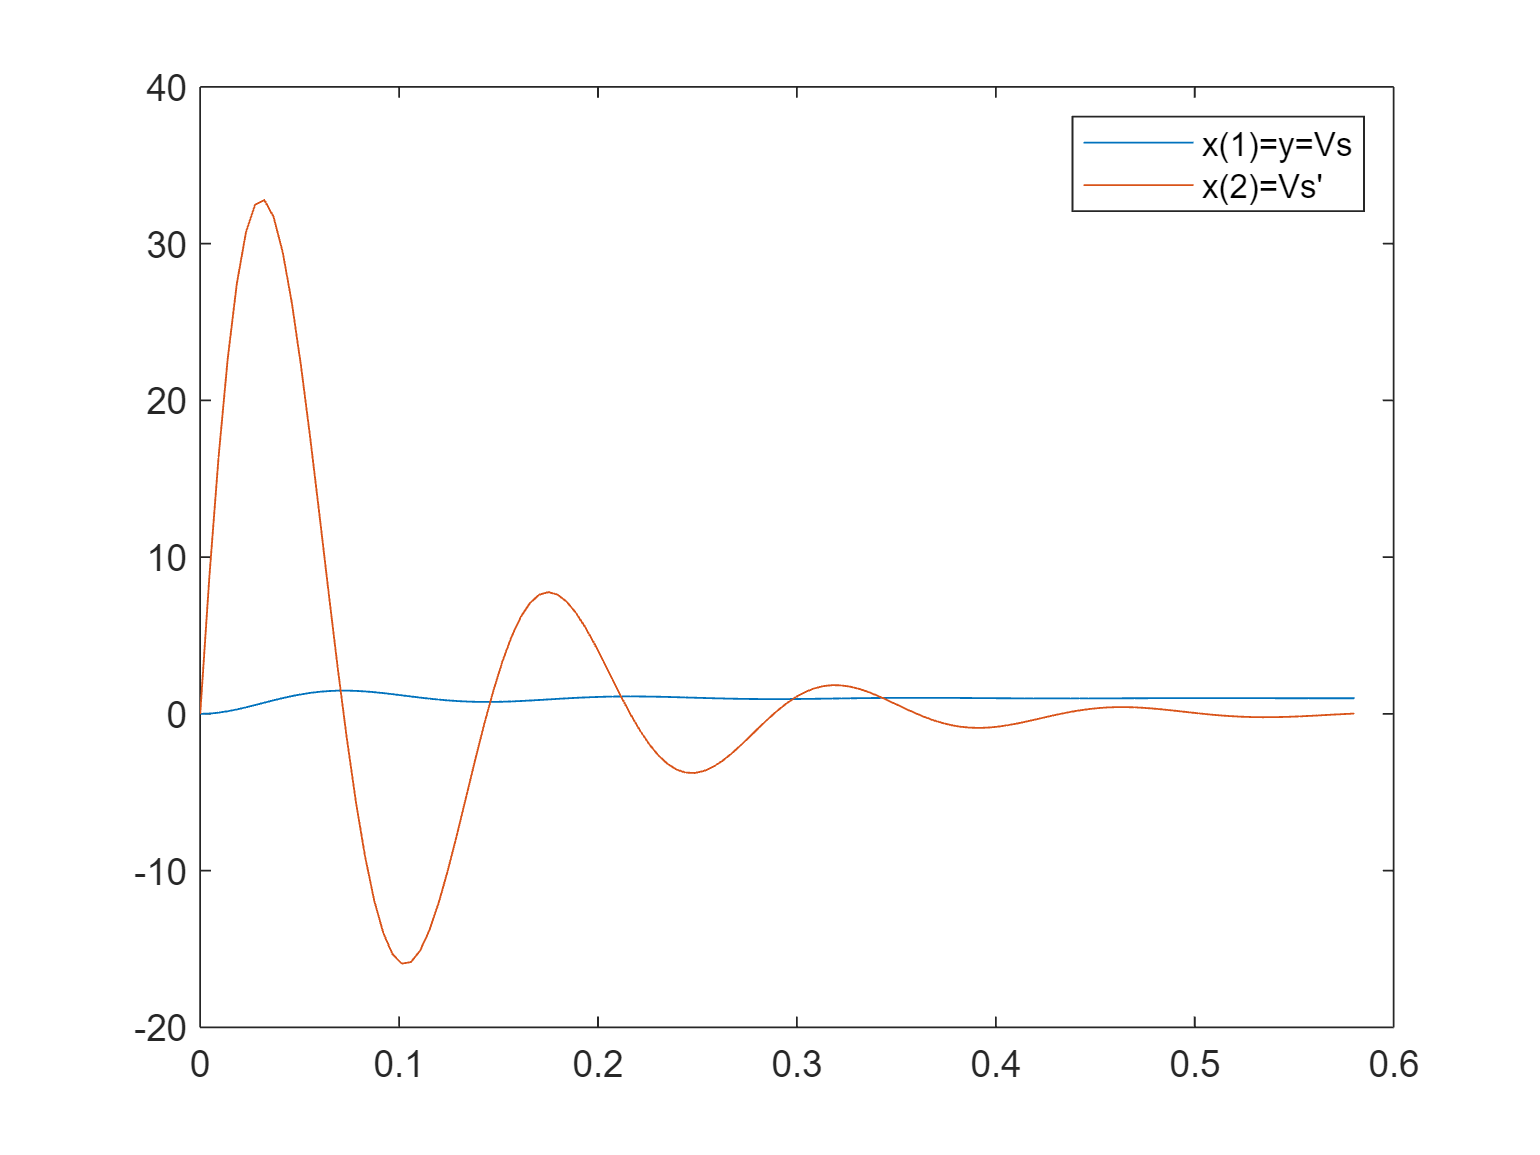

% El siguiente comando, que veremos con más detalle más adelante, simula
% la respuesta del sistema ante una entrada escalón unitario, y devuelve
% el valor de la salida y en los instantes de tiempo t, así como los
% valores de las variables de estado en x
[y,t,x] = step(sys_LRC);
% Mostramos la evolución de las variables de estado
plot(t,x), legend('x(1)=y=Vs',"x(2)=Vs'")

¡Apliquemos lo aprendido!

**Tarea 1:** En la figura se representa un cilindro hidráulico, cuyo émbolo de sección $a=0,1m^2$ y masa $m=1\textrm{kg}$ es accionado por una presión `p` de entrada. 

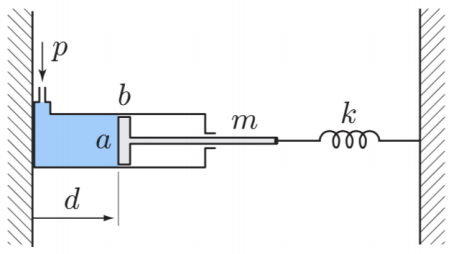

En este sistema se mide la distancia $d$ (salida) que se comprime un muelle de constante $k=0,4\textrm{kg}/s^2 ,$ el cual se halla en reposo con $d=0$. Además, se halla presente una resistencia al movimiento de coeficiente $b=0,4\textrm{kg}/s$, de forma que la ecuación diferencial es: 


$$m\overset{\cdot \cdot }{d} =-b\overset{\cdot }{d} -\textrm{kd}+\textrm{ap}$$


Se pide:

        1. Obtener una representación interna del sistema.

% Tu código aquí

a = 0.1;
m = 1;
k = 0.4;
d = 0; 
b = 0.4; 
A = [0 1;-k/m -b/m];
B = [0;a/m];
C = [1 0];
D = [0];
sys = ss(A,B,C,D)

sys =
 
  A = 
         x1    x2
   x1     0     1
   x2  -0.4  -0.4
 
  B = 
        u1
   x1    0
   x2  0.1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


Resultado esperado:

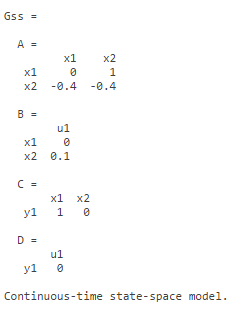

**Tarea 2:** La siguiente figura muestra el esquema eléctrico de un circuito RCRC:

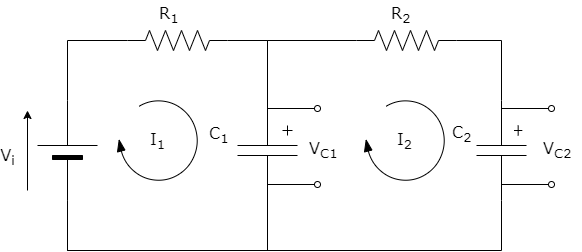

El comportamiento dinámico de dicho sistema, empleando la ley de tensiones de Kirchhoff, puede modelarse matemáticamente por medio de las siguientes ecuaciones diferenciales:


$$\begin{array}{l}
\left.\textrm{malla}\;1\right){\;V}_i =V_{\textrm{R1}} +V_{\textrm{C1}} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;{\;V}_i =I_1 R_1 +V_{\textrm{C1}} \\
\left.\textrm{malla}\;2\right)\;V_{\textrm{C1}} =V_{\textrm{R2}} +V_{\textrm{C2}} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;V_{\textrm{C1}} =I_2 R_2 +V_{\textrm{C2}} 
\end{array}$$


Teniendo en cuenta que $V_{\textrm{C1}} =\frac{1}{C_1 }\int \left(I_1 -I_2 \right)\textrm{dt}$ y $V_{\textrm{C2}} =\frac{1}{C_2 }\int \;I_2 \;\textrm{dt}$, obtener la representación en espacio de estados teniendo en cuentra que:

- la entrada al sistema es la tensión $V_i$,

- las variables de estado serán $x_1 =V_{\textrm{C1}}$ y $x_2 =V_{\textrm{C2}}$, es decir, la caída de tensión en los condensadores, y

- la salida del sistema es la caída de tensión en el primer condensador, $y=V_{\textrm{C1}}$.

- Los valores que toman las resistencias y las capacitancias se dan en la celda de código.

*Pista:** Trata de despejar las dos corrientes y de sustituirlas en las ecuaciones obtenidas en las mallas, así se podrán obtener dos ecuaciones donde aparezcan las derivadas de las dos tensiones, facilitando la construcción de la representación en espacio de estados.*

R1 = 8; R2 = 800; C1 = 12*10^-6; C2 = 20*10^-6;
% Tu código aquí
%Hecho en foto
A=[-1/(C1*R2)-1/(R1*C1) 1/(C1*R2); 1/(R2*C2) -1/(R2*C2)];
B=[1/(R1*C1); 0];
C=[1 0];
D=[0];

sys2 = ss(A,B,C,D)

sys2 =
 
  A = 
               x1          x2
   x1  -1.052e+04       104.2
   x2        62.5       -62.5
 
  B = 
              u1
   x1  1.042e+04
   x2          0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


`Resultado esperado:`

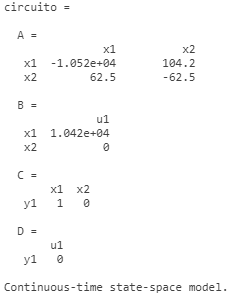

### `1.3 Puntos de equilibrio`

Los puntos de **equilibrio**, también llamados puntos de **operación** o **consigna**,  son puntos en el espacio de estados donde el sistema puede permanecer operando con actuaciones pequeñas y constantes alrededor de dicho punto. Los puntos que cumplen con esta caracteristica son aquellos en los que las derivadas de las variables de estado se anulan.

Estos puntos son especialmente útiles a la hora de linealizar sistemas, ya que nos permiten aproximar un sistema no lineal alrededor de dicho punto y tratarlo como lineal dentro de un cierto rango de operación. Tenemos una sesión práctica especialmente dedicada a la linealización de sistemas, pero vamos a ir adelantando trabajo con el procedimiento de obtención de **puntos de equilibrio**. 

Vamos con un ejemplo. En el contexto de nuestro querido circuito LRC, recordemos cuales son las derivadas de las variables de estado:

- 
$${\overset{\cdot }{x} }_1 =x_2$$


- 
$${\overset{\cdot }{x} }_2 =-\frac{1}{\textrm{LC}}x_1 -\frac{R}{L}x_2 +\frac{1}{\textrm{LC}}u$$


- 
$$y=x_1$$


Si procedemos igualandolas a cero, obtenemos:

- 
$${\overset{\cdot }{x} }_1 =0\;\Rightarrow x_{2e} =0$$


- 
$${\overset{\cdot }{x} }_2 =0\Rightarrow -\frac{1}{\textrm{LC}}x_{1e} +\frac{1}{\textrm{LC}}u_e =0\Rightarrow x_{1e} =u_e$$


- 
$$y=u_e$$


Estas operaciones también podemos realizarlas usando el fabuloso cálculo simbólico de MATLAB:  

syms L C R x1 x2 ue
A = [0 1; -1/(L*C) -R/L]; % matriz dinámica
B = [0; 1/(L*C)];         % matriz de control
C = [1 0];                % matriz de salida
D = [0];                  % matriz de influencia directa
[x1e x2e] = solve(0==A*[x1;x2]+B*ue)

$$x1e = \mathrm{ue}$$

$$x2e = 0$$

ye = C*[x1e; x2e] + D*ue

$$ye = \mathrm{ue}$$

**Tarea 3:** Calcular los puntos de equilibrio de la descripción interna definida en la Tarea 1, tanto en papel como usando MATLAB.

Pista: Emplea `help syms` y `help solve` para obtener más información acerca de estos fantásticos comandos.

% Tu código aquí


syms x1 x2 ue
a = 0.1;
m = 1;
k = 0.4;
d = 0; 
b = 0.4; 
A=[0 1; -k/m -b/m];
B=[0; a];
C=[1 0];
D=[0];

[x1e x2e] = solve (0==A*[x1;x2]+B*ue)

$$x1e = \frac{\mathrm{ue}}{4}$$

$$x2e = 0$$

ye=C*[x1e; x2e] + D*ue

$$ye = \frac{\mathrm{ue}}{4}$$

Resultado esperado: